# Question - 1 (PART- II)

% Clear workspace and command window
clear; clc; close all;
% For reproducibility
rng(13); 

## Given Data


N = 20;  % Number of Observations
R = 200; % Number of Realizations
beta = [0;3;5]; % True Beta

## Initialize variables


beta_estimates_ols = zeros(R, 3); % Store parameter estimates
beta_estimates_lms = zeros(R, 3);
beta_estimates_lts = zeros(R, 3);
loss_ols = zeros(R, 1); % Store final cost
loss_lms = zeros(R, 1); 
loss_lts = zeros(R, 1); 
alpha = 0.01; % Learning rate
epochs = [200, 150, 800]; % Epochs or Number of Iterations

## Perform Regression for R realizations

for r = 1:R
    % Generate Data
    X1 = randn(N, 1);
    X2 = randn(N, 1);
    E = randn(N, 1);
    y = beta(2)*X1 + beta(3)*X2 + E;
    X = [X1 X2];
    
    % Perform Regression
    [beta_hat_ols, cost_history_ols] = ordinaryLeastSquares(X, y, alpha, epochs(1));
    [beta_hat_lms, cost_history_lms] = leastMedianSquares(X, y, alpha, epochs(2));
    [beta_hat_lts, cost_history_lts] = leastTrimmedSquares(X, y, alpha, epochs(3));
    
    % Record final variables value
    beta_estimates_ols(r, :) = beta_hat_ols';
    loss_ols(r) = cost_history_ols(end);
    
    beta_estimates_lms(r, :) = beta_hat_lms';
    loss_lms(r) = cost_history_lms(end);
    
    beta_estimates_lts(r, :) = beta_hat_lts';
    loss_lts(r) = cost_history_lts(end);
end

## Best beta across realizations

% Find the realization with the minimum sum of squared residuals
[min_ssr_ols, best_parameter_ols] = min(loss_ols);
[min_ssr_lms, best_parameter_lms] = min(loss_lms);
[min_ssr_lts, best_parameter_lts] = min(loss_lts);
fprintf('Best realization Index - OLS: %d\n\n', best_parameter_ols);

Best realization Index - OLS: 116



fprintf('Best realization Index - LMS: %d\n\n', best_parameter_lms);

Best realization Index - LMS: 179



fprintf('Best realization Index - LTS: %d\n\n', best_parameter_lts);

Best realization Index - LTS: 88



best_estimates = [beta_estimates_ols(best_parameter_ols, :)' beta_estimates_lms(best_parameter_lms, :)' beta_estimates_lts(best_parameter_lts, :)'];
% Display best parameters
% Model parameter names
parameters = {'beta0', 'beta1', 'beta2'};
methods = {'OLS', 'LMS', 'LTS'};
TP = table(best_estimates(:, 1), best_estimates(:, 2), best_estimates(:, 3), 'VariableNames', methods);
TPD = table(parameters', TP, 'VariableNames', {'Parameters', 'Optimum'});
disp(TPD);

    Parameters                 Optimum             
                     OLS         LMS         LTS   
    __________    _________________________________

     'beta0'      0.0076753    -0.03846    -0.32516
     'beta1'         2.7235      2.8845      2.3579
     'beta2'         4.5065      4.8435      4.1158



TL = table(methods', [min_ssr_ols, min_ssr_lms, min_ssr_lts]', 'VariableNames', {'Methods', 'Loss'});
TLD = table(TL, 'VariableNames', {'Minimum_Loss_across_R'});
disp(TLD);

    Minimum_Loss_across_R
    Methods      Loss    
    _____________________

     'OLS'          0.53 
     'LMS'     0.0013857 
     'LTS'       0.15288 



## Model Testing

% Generate Test Data
rng(27); % Change reproducibility to generate new data
X1 = randn(N, 1);
X2 = randn(N, 1);
E = randn(N, 1);
y = beta(2)*X1 + beta(3)*X2 + E;
X = [X1 X2];

**Ordinary Least Squares**

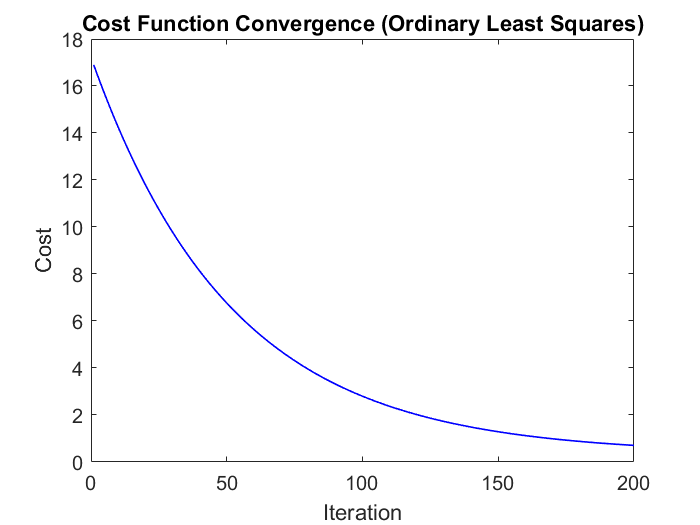

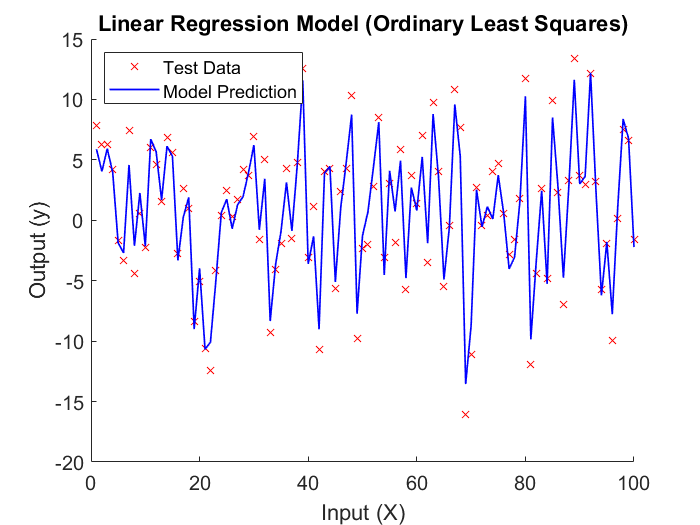

plotresult(X, y, best_estimates(:,1), epochs(1), cost_history_ols, "Ordinary Least Squares")

**Least Median Squares**

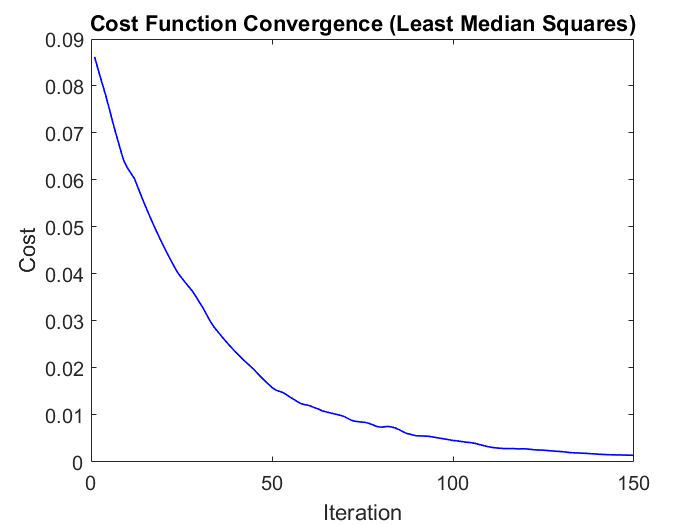

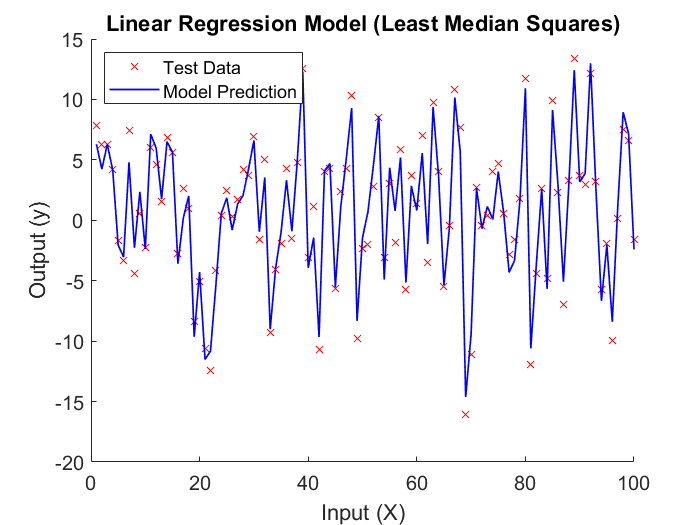

plotresult(X, y, best_estimates(:,2), epochs(2), cost_history_lms, "Least Median Squares")

**Least Trimmed Squares**

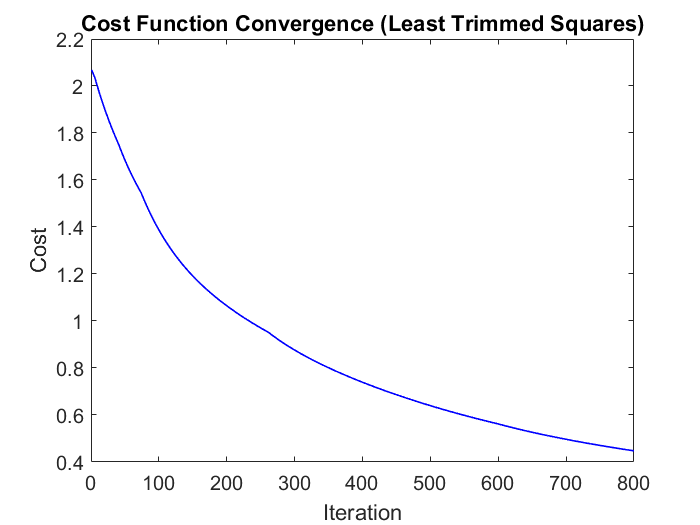

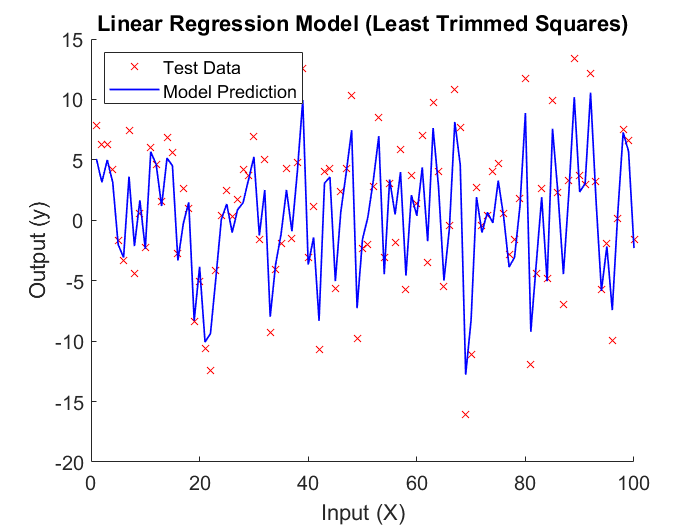

plotresult(X, y, best_estimates(:,3), epochs(3), cost_history_lts, "Least Trimmed Squares")

## Model Comparison

% Calculate metrics
metrics_ols = metrics(beta, beta_estimates_ols);
metrics_lms = metrics(beta, beta_estimates_lms);
metrics_lts = metrics(beta, beta_estimates_lts);

% Comparison Metrics
cmetrics = {'MSE', 'RB', 'MAD'};

% Display metrics
TM = table(metrics_ols', metrics_lms', metrics_lts', 'VariableNames', methods);
TMD = table(cmetrics', TM, 'VariableNames', {'Parameters', 'Metrics'});
disp(TMD);

    Parameters               Metrics            
                    OLS         LMS        LTS  
    __________    ______________________________

      'MSE'       0.034016    0.01881    0.26578
      'RB'          6.7453     8.1251     3.9865
      'MAD'         18.367     22.303     10.385

